% ebfret_viterbi_beadplot_examples.mlx: using ebfret_viterbi_beadplot() to produce 
% unsorted and sorted viterbi rastergrams
%
% example data was made by saving the output variable produced by ebfret
load 'e4.mat'

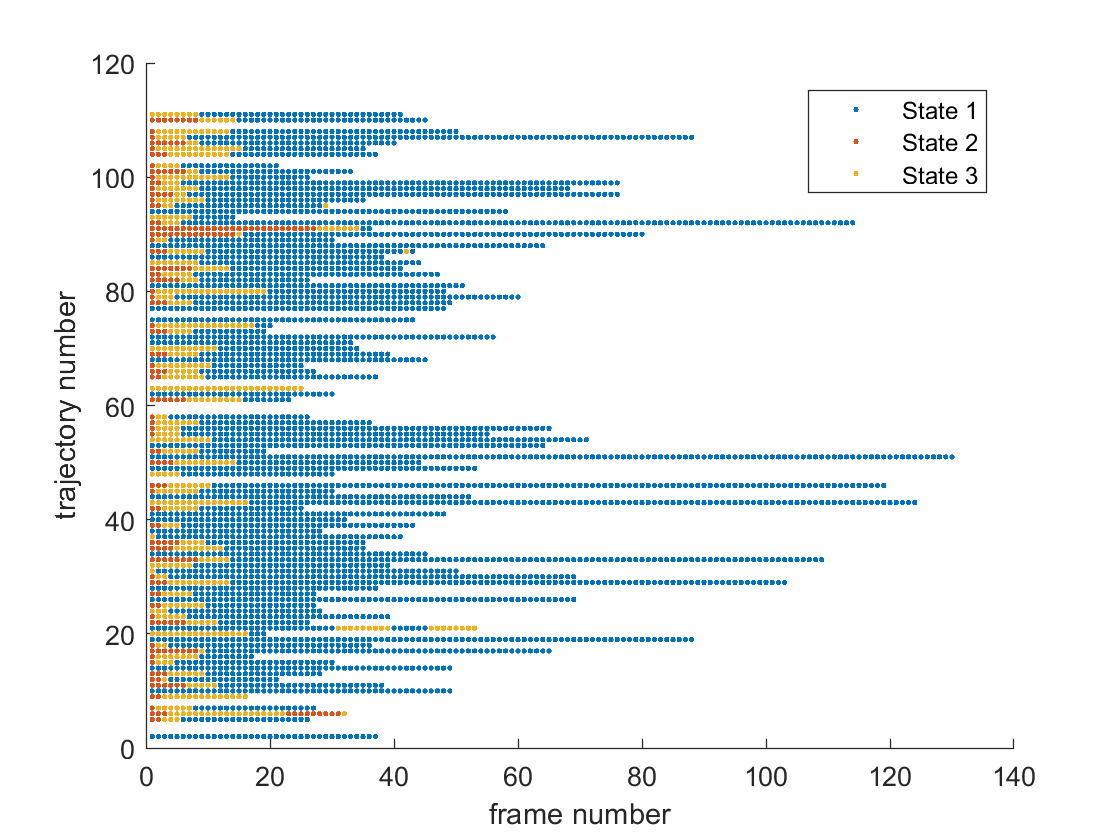

% unsorted
nstates = 3;
ebfret_viterbi_beadplot(analysis, nstates)

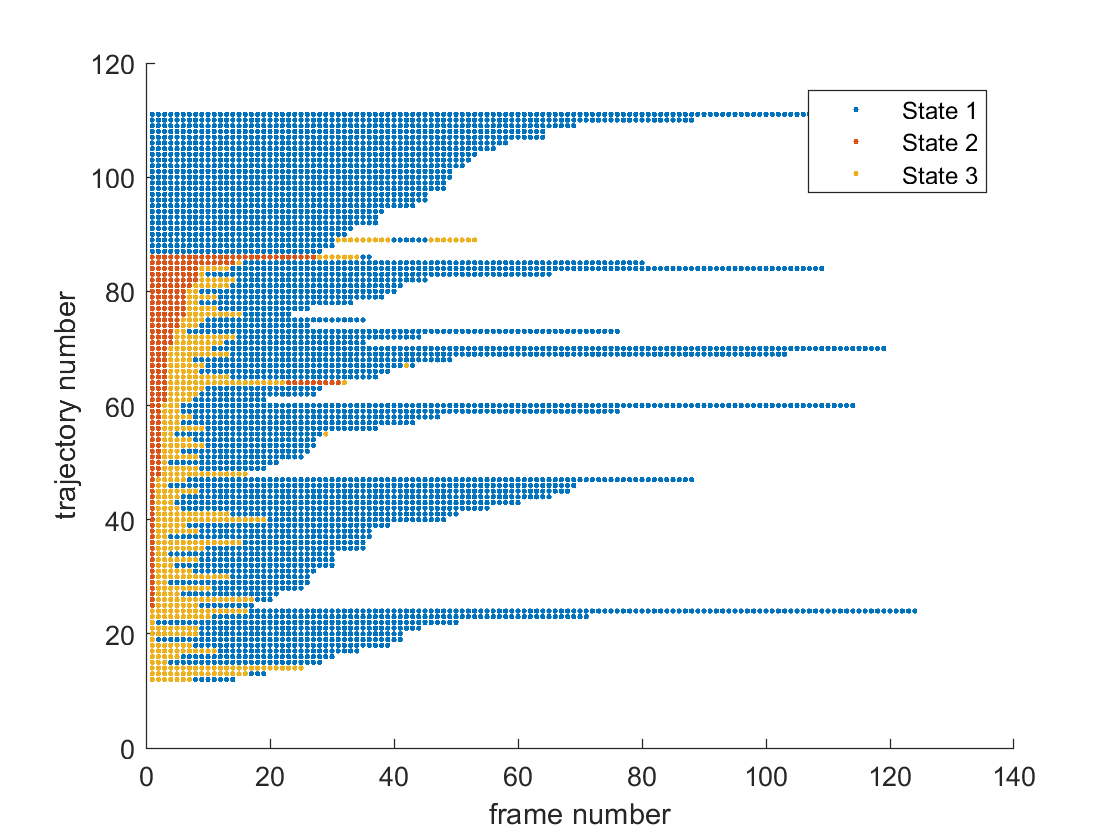

% same data, now sorted
trajectories=length(analysis(nstates).viterbi);
for itraj = 1:trajectories
  s=analysis(nstates).viterbi(itraj).state;
  ind = find(s == 3, 1); % sort criterion: first point in state 3
  if isempty(ind)
      ind = length(s) + 1; % sort by length of trajectory if no points in state 3
  end
  sortkey(itraj, 1) = ind; % primary sort key
  sortkey(itraj, 2) = length(s); % secondary sort key, used to break ties of primary key
end
[~, indlist] = sortrows(sortkey);
analysis2 = analysis;
analysis2(nstates).viterbi(:) = analysis(nstates).viterbi(indlist);
ebfret_viterbi_beadplot(analysis2, nstates)

jganalyze_gitinfo()

ans = struct with fields:
    branch: 'master'
      hash: '37969b2edbbb23ed9d9e5767345ea9b86be79d9f'
    remote: 'origin'
       url: 'https://github.com/gelles-brandeis/jganalyze.git'
